% Q1
M = zeros(7,5);
M(1:2,4:5) = 1;
for i = 3:1:7
    M(i,i-2) = 1;
end

m1 = zeros(2,3);
m2 = ones(2,2);
m3 = eye(5,5);
m = [m1 m2; m3];

a = 3:1:7;
A1 = [a;a+10];

A2 = zeros(2,5);
for i = 3:1:7
    A2(1,i-2)=i;
    A2(2,i-2)=i+10;
end

% X = [x;y;z]
% DX = B
D = [2 -3 4; 1 1 4; 3 4 -2;];
B = [5;10;0;];
X = inv(D)*B;

syms x y z
eqn1 = 2*x-3*y+4*z==5;
eqn2 = y+4*z+x==10;
eqn3 = -2*z+3*x+4*y==0;
sol = solve(eqn1,eqn2,eqn3);
X = [sol.x;sol.y;sol.z];

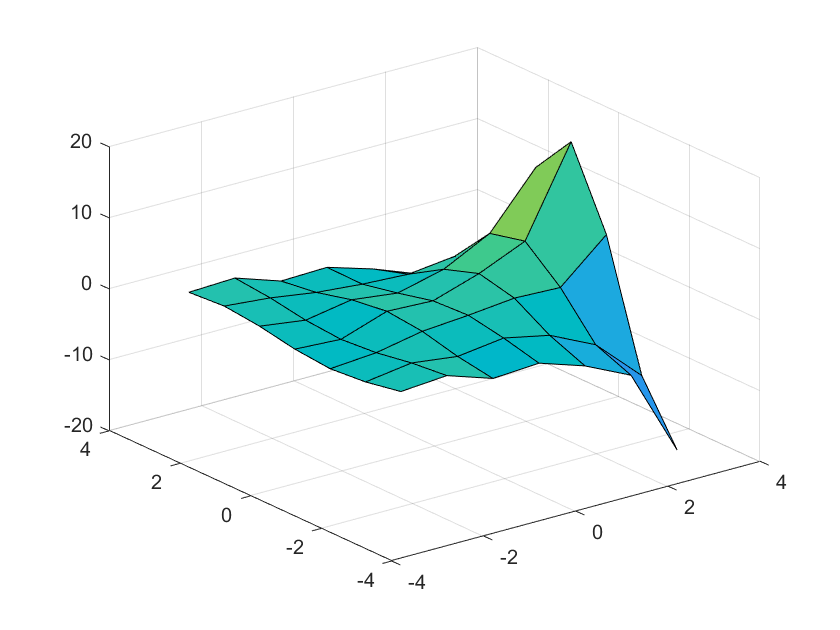

Z_34=Z(-3,4);
Z5_7=Z(5,-7);
x = -pi:1:pi;
y = -pi:1:pi;
[x,y] = meshgrid(x,y);
z = Z(x,y);
surf(x,y,z);